刘开元设计的峰值查询函数

## 语法

## 示例

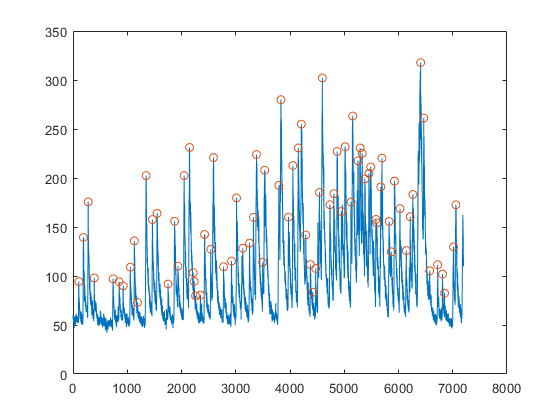

## 输入参数

Data(1,:)，数据向量

### 名称值参数

SampleRate=8，采样率㎐

WindowRadius=5，滑窗半径，单位帧，不能大于SampleRate的2倍。峰值前后WindowRadius范围内的值将被用于验证峰值的有效性，实际窗尺寸为WindowRadius*2+1。

AucThreshold=1.2，窗内AUC必须大于这个阈值才会被视为一个有效峰。这个值是从基线归一化过的。

## 返回值

PeakTimes(1,:)，所有找到的峰值时点，单位帧

function PeakTimes = LkyFindPeaks(Data,options)
arguments
	Data
	options.SampleRate=8
	options.WindowRadius=5
	options.AucThreshold=1.2
end
%从刘开元原始代码中拷贝，并经Bito优化
% Calculate histogram data without plotting
[counts, edges] = histcounts(Data, 20);

% Find the bin with the maximum count
[~, max_id] = max(counts);

% Normalize data1 based on the calculated base
Data = Data*2 / (edges(max_id) + edges(max_id + 1))-1;
PeakTimes=MATLAB.Containers.Vector;

stats_time_fps = 8 * options.SampleRate; % Pre-calculate repeated constant
middleStart = floor(stats_time_fps / 4);
middleEnd = stats_time_fps - middleStart+1;
PointerEnd=numel(Data) - stats_time_fps;
MedianThreshold=options.AucThreshold / (2 * options.WindowRadius + 1);
Pointer = middleStart-1;
while Pointer <= PointerEnd
	datak = Data(Pointer:Pointer + stats_time_fps);
	[~, maxIndex] = max(datak);
	if maxIndex<middleStart
		Pointer=Pointer+maxIndex;
	elseif maxIndex>middleEnd
		Pointer=Pointer+maxIndex-middleEnd;
	else
		if sum(datak(maxIndex -options.WindowRadius:maxIndex + options.WindowRadius)) > options.AucThreshold && median(datak(maxIndex:maxIndex+3)) > MedianThreshold
			PeakTimes.PushBack(Pointer + maxIndex - 1); % Save the peak time
			Pointer = Pointer + maxIndex; % Jump to the next index after the current peak
		else
			Pointer = Pointer+middleStart + 1; % Increment if no peak is found
		end
	end
end
PeakTimes = PeakTimes.Data;